clear;
clc;

1）r=50, x=0`：`

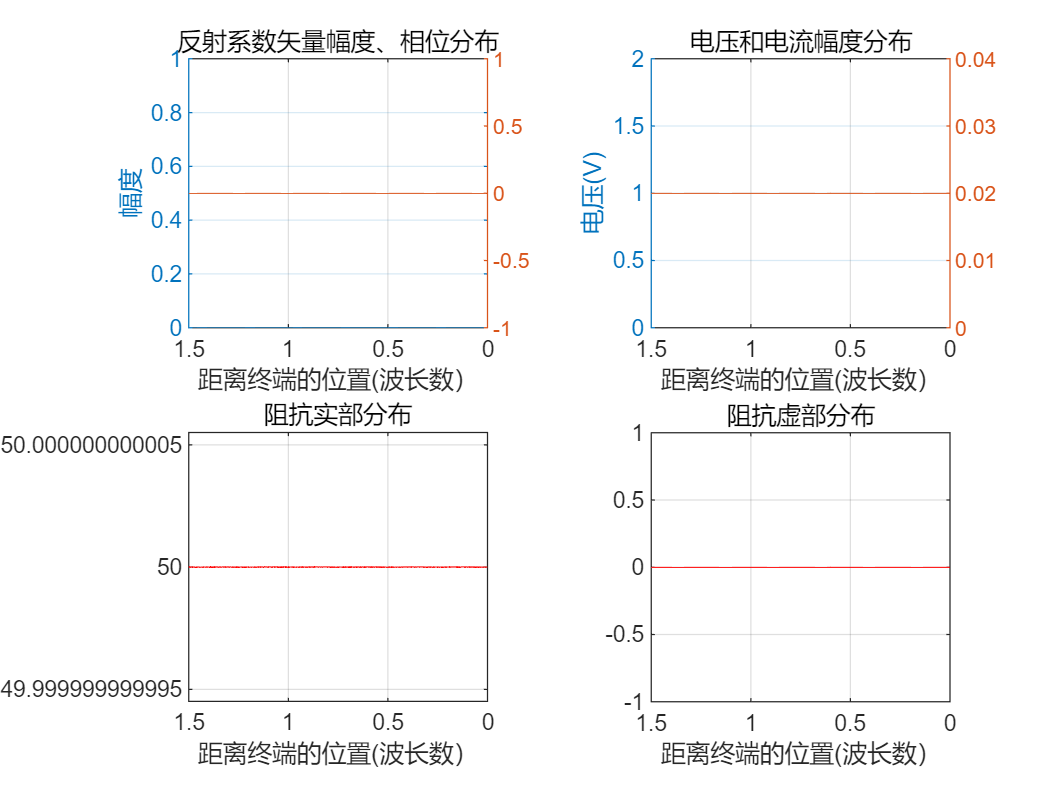

%%%%%%%%%实验条件%%%%%%%%%
Vg=2;
Z0=50;
Rg=50;
Zl=50+0*1i;

%%%%%%%%%参数设置%%%%%%%%%
ztp=0:0.001:1.5;% 位置步长
err=10^(-8);% 精度

%%%%%%%%%公式%%%%%%%%%
% 1.	终端反射系数
gamma0=(Zl-Z0)/(Zl+Z0);
% 2.	传输线上反射系数分布
gamma=gamma0*exp(-1i*4*pi*ztp);
% 3.	传输线上输入阻抗分布
Zin=Z0*(Zl*cos(2*pi*ztp)+1i*Z0*sin(2*pi*ztp))./(Z0*cos(2*pi*ztp)+1i*Zl*sin(2*pi*ztp));
% 4.	源端（即输入端）输入反射系数和输入阻抗
gammaL=gamma0*exp(-1i*2*2*pi*1.5);
ZinL=Z0*(Zl*cos(2*pi*1.5)+1i*Z0*sin(2*pi*1.5))/(Z0*cos(2*pi*1.5)+1i*Zl*sin(2*pi*1.5));
% 5.	源端（即输入端）电压、电流和入射波电压
VL=Vg*ZinL/(Rg+ZinL);
CL=VL/ZinL;
Vinc=(VL+CL*Z0)/2;
% 6.	负载端（即坐标原点处）入射波电压
A1=Vinc*exp(-1i*2*pi*1.5);
% 7.	传输线上电压和电流分布
v_ca0=A1*exp(1i*2*pi*ztp);%幅值
v_ca=v_ca0.*(1+gamma);
i_ca=v_ca0.*(1-gamma)/Z0;



%%%%%%%%%绘制图像%%%%%%%%%
figure(1);
%反射系数幅度和相位分布曲线
subplot(2,2,1);
ax = plotyy(ztp,abs(gamma),ztp,angle(gamma)*180/pi);
set(ax(1),'ylim',[0,1],'ytick',[0:0.2:1]);
set(get(ax(1),'Ylabel'),'string','幅度');
title('反射系数矢量幅度、相位分布');
set(ax,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
%电压电流大小分布曲线
subplot(2,2,2);
ax = plotyy(ztp,abs(v_ca),ztp,abs(i_ca));
set(ax(1),'ylim',[0,Vg],'ytick',[0:Vg/4:Vg]);
set(get(ax(1),'Ylabel'),'string','电压(V)');
set(ax(2),'ylim',[0,Vg/Z0],'ytick',[0:Vg/4/Z0:Vg/Z0]);
title('电压和电流幅度分布');
set(ax,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
%阻抗实部分布曲线
subplot(2,2,3);
realZin = max(-1000,min(1000,real(Zin))); %限制大小在+/-1000以内
plot(ztp,realZin,'r');
title('阻抗实部分布');
set(gca,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
%阻抗虚部分布曲线
subplot(2,2,4);
imagZin = max(-1000,min(1000,imag(Zin))); %限制大小在+/-1000以内
if(max(abs(imagZin)))<err
    imagZin = imagZin*0;
end
plot(ztp,imagZin,'r');
title('阻抗虚部分布');
set(gca,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;

clear;
clc;

2）r=0, x=0`：`

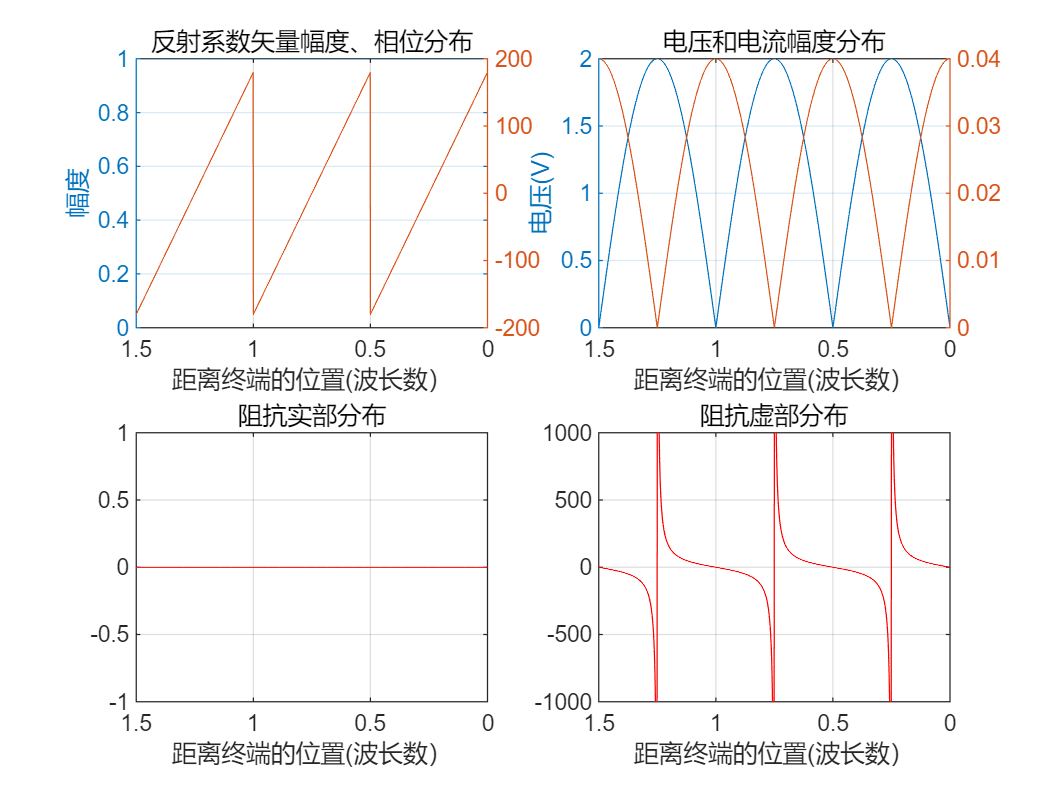

%%%%%%%%%实验条件%%%%%%%%%
Vg=2;
Z0=50;
Rg=50;
Zl=0+0*1i;

%%%%%%%%%参数设置%%%%%%%%%
ztp=0:0.001:1.5;% 位置步长
err=10^(-8);% 精度

%%%%%%%%%公式%%%%%%%%%
% 1.	终端反射系数
gamma0=(Zl-Z0)/(Zl+Z0);
% 2.	传输线上反射系数分布
gamma=gamma0*exp(-1i*4*pi*ztp);
% 3.	传输线上输入阻抗分布
Zin=Z0*(Zl*cos(2*pi*ztp)+1i*Z0*sin(2*pi*ztp))./(Z0*cos(2*pi*ztp)+1i*Zl*sin(2*pi*ztp));
% 4.	源端（即输入端）输入反射系数和输入阻抗
gammaL=gamma0*exp(-1i*2*2*pi*1.5);
ZinL=Z0*(Zl*cos(2*pi*1.5)+1i*Z0*sin(2*pi*1.5))/(Z0*cos(2*pi*1.5)+1i*Zl*sin(2*pi*1.5));
% 5.	源端（即输入端）电压、电流和入射波电压
VL=Vg*ZinL/(Rg+ZinL);
CL=VL/ZinL;
Vinc=(VL+CL*Z0)/2;
% 6.	负载端（即坐标原点处）入射波电压
A1=Vinc*exp(-1i*2*pi*1.5);
% 7.	传输线上电压和电流分布
v_ca0=A1*exp(1i*2*pi*ztp);%幅值
v_ca=v_ca0.*(1+gamma);
i_ca=v_ca0.*(1-gamma)/Z0;



%%%%%%%%%绘制图像%%%%%%%%%
figure(1);
%反射系数幅度和相位分布曲线
subplot(2,2,1);
ax = plotyy(ztp,abs(gamma),ztp,angle(gamma)*180/pi);
set(ax(1),'ylim',[0,1],'ytick',[0:0.2:1]);
set(get(ax(1),'Ylabel'),'string','幅度');
title('反射系数矢量幅度、相位分布');
set(ax,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
%电压电流大小分布曲线
subplot(2,2,2);
ax = plotyy(ztp,abs(v_ca),ztp,abs(i_ca));
set(ax(1),'ylim',[0,Vg],'ytick',[0:Vg/4:Vg]);
set(get(ax(1),'Ylabel'),'string','电压(V)');
set(ax(2),'ylim',[0,Vg/Z0],'ytick',[0:Vg/4/Z0:Vg/Z0]);
title('电压和电流幅度分布');
set(ax,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
%阻抗实部分布曲线
subplot(2,2,3);
realZin = max(-1000,min(1000,real(Zin))); %限制大小在+/-1000以内
plot(ztp,realZin,'r');
title('阻抗实部分布');
set(gca,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
%阻抗虚部分布曲线
subplot(2,2,4);
imagZin = max(-1000,min(1000,imag(Zin))); %限制大小在+/-1000以内
if(max(abs(imagZin)))<err
    imagZin = imagZin*0;
end
plot(ztp,imagZin,'r');
title('阻抗虚部分布');
set(gca,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;

clear;
clc;

3）r=1000, x=1000`：`

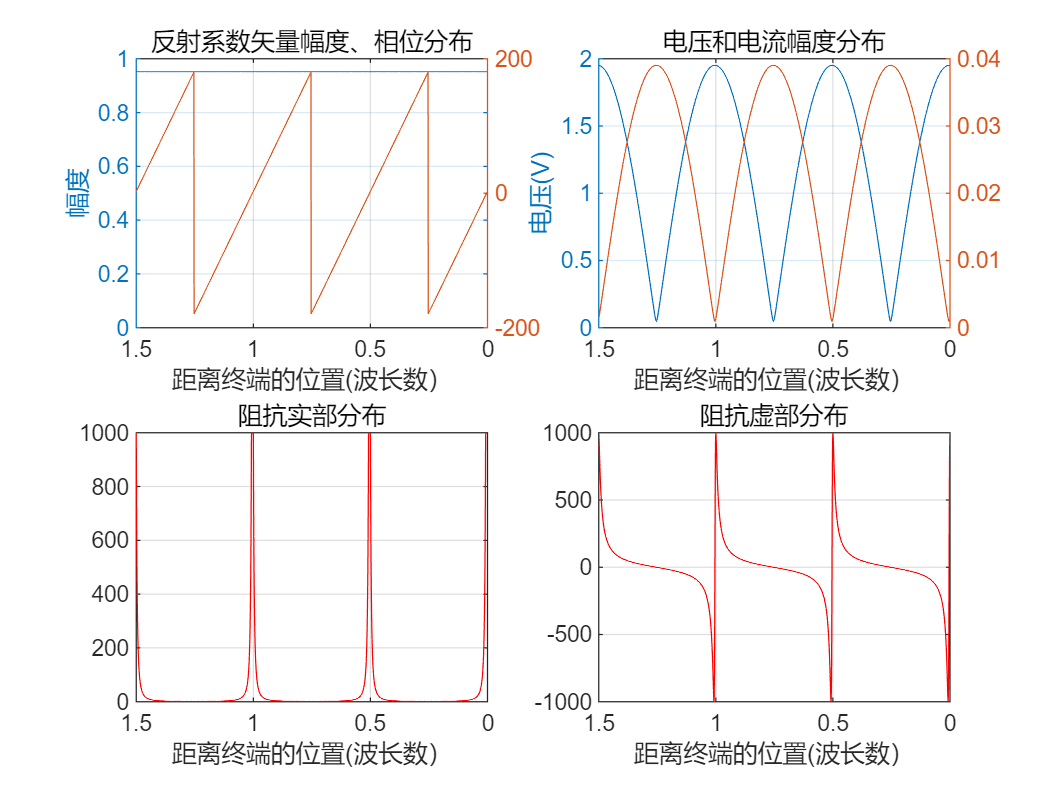

%%%%%%%%%实验条件%%%%%%%%%
Vg=2;
Z0=50;
Rg=50;
Zl=1000+1000*1i;

%%%%%%%%%参数设置%%%%%%%%%
ztp=0:0.001:1.5;% 位置步长
err=10^(-8);% 精度

%%%%%%%%%公式%%%%%%%%%
% 1.	终端反射系数
gamma0=(Zl-Z0)/(Zl+Z0);
% 2.	传输线上反射系数分布
gamma=gamma0*exp(-1i*4*pi*ztp);
% 3.	传输线上输入阻抗分布
Zin=Z0*(Zl*cos(2*pi*ztp)+1i*Z0*sin(2*pi*ztp))./(Z0*cos(2*pi*ztp)+1i*Zl*sin(2*pi*ztp));
% 4.	源端（即输入端）输入反射系数和输入阻抗
gammaL=gamma0*exp(-1i*2*2*pi*1.5);
ZinL=Z0*(Zl*cos(2*pi*1.5)+1i*Z0*sin(2*pi*1.5))/(Z0*cos(2*pi*1.5)+1i*Zl*sin(2*pi*1.5));
% 5.	源端（即输入端）电压、电流和入射波电压
VL=Vg*ZinL/(Rg+ZinL);
CL=VL/ZinL;
Vinc=(VL+CL*Z0)/2;
% 6.	负载端（即坐标原点处）入射波电压
A1=Vinc*exp(-1i*2*pi*1.5);
% 7.	传输线上电压和电流分布
v_ca0=A1*exp(1i*2*pi*ztp);%幅值
v_ca=v_ca0.*(1+gamma);
i_ca=v_ca0.*(1-gamma)/Z0;



%%%%%%%%%绘制图像%%%%%%%%%
figure(1);
%反射系数幅度和相位分布曲线
subplot(2,2,1);
ax = plotyy(ztp,abs(gamma),ztp,angle(gamma)*180/pi);
set(ax(1),'ylim',[0,1],'ytick',[0:0.2:1]);
set(get(ax(1),'Ylabel'),'string','幅度');
title('反射系数矢量幅度、相位分布');
set(ax,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
%电压电流大小分布曲线
subplot(2,2,2);
ax = plotyy(ztp,abs(v_ca),ztp,abs(i_ca));
set(ax(1),'ylim',[0,Vg],'ytick',[0:Vg/4:Vg]);
set(get(ax(1),'Ylabel'),'string','电压(V)');
set(ax(2),'ylim',[0,Vg/Z0],'ytick',[0:Vg/4/Z0:Vg/Z0]);
title('电压和电流幅度分布');
set(ax,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
%阻抗实部分布曲线
subplot(2,2,3);
realZin = max(-1000,min(1000,real(Zin))); %限制大小在+/-1000以内
plot(ztp,realZin,'r');
title('阻抗实部分布');
set(gca,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
%阻抗虚部分布曲线
subplot(2,2,4);
imagZin = max(-1000,min(1000,imag(Zin))); %限制大小在+/-1000以内
if(max(abs(imagZin)))<err
    imagZin = imagZin*0;
end
plot(ztp,imagZin,'r');
title('阻抗虚部分布');
set(gca,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;

clear;
clc;

4）r=0, x=10`：`

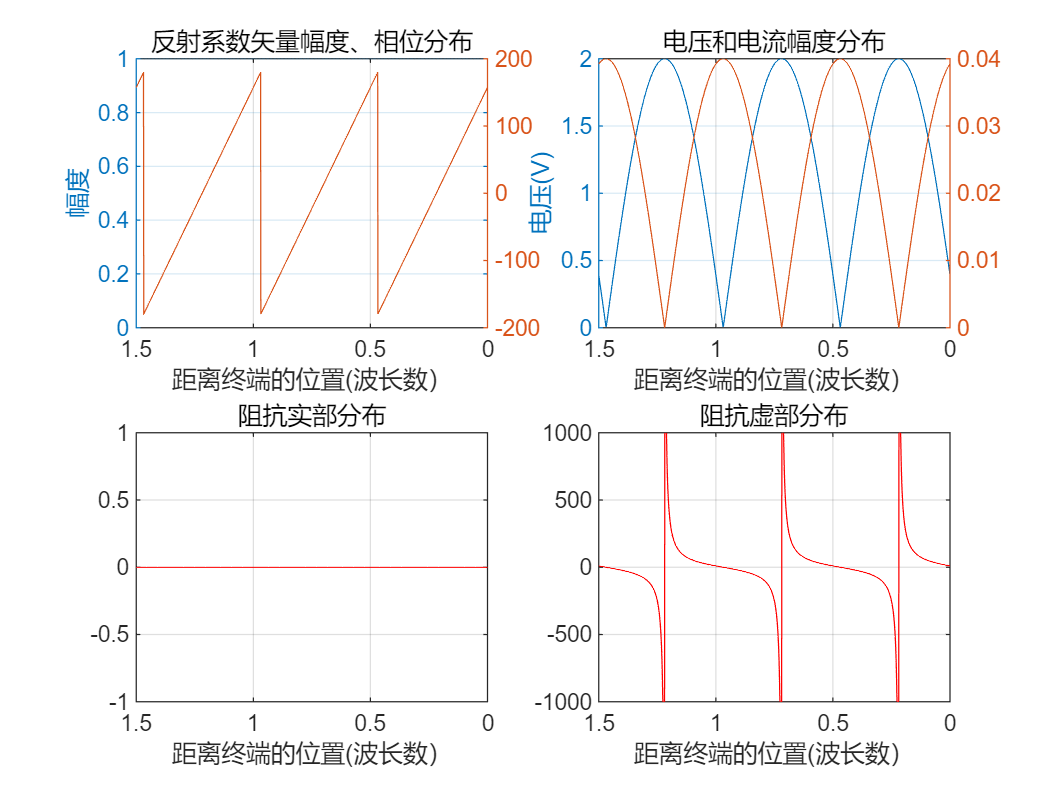

%%%%%%%%%实验条件%%%%%%%%%
Vg=2;
Z0=50;
Rg=50;
Zl=0+10*1i;

%%%%%%%%%参数设置%%%%%%%%%
ztp=0:0.001:1.5;% 位置步长
err=10^(-8);% 精度

%%%%%%%%%公式%%%%%%%%%
% 1.	终端反射系数
gamma0=(Zl-Z0)/(Zl+Z0);
% 2.	传输线上反射系数分布
gamma=gamma0*exp(-1i*4*pi*ztp);
% 3.	传输线上输入阻抗分布
Zin=Z0*(Zl*cos(2*pi*ztp)+1i*Z0*sin(2*pi*ztp))./(Z0*cos(2*pi*ztp)+1i*Zl*sin(2*pi*ztp));
% 4.	源端（即输入端）输入反射系数和输入阻抗
gammaL=gamma0*exp(-1i*2*2*pi*1.5);
ZinL=Z0*(Zl*cos(2*pi*1.5)+1i*Z0*sin(2*pi*1.5))/(Z0*cos(2*pi*1.5)+1i*Zl*sin(2*pi*1.5));
% 5.	源端（即输入端）电压、电流和入射波电压
VL=Vg*ZinL/(Rg+ZinL);
CL=VL/ZinL;
Vinc=(VL+CL*Z0)/2;
% 6.	负载端（即坐标原点处）入射波电压
A1=Vinc*exp(-1i*2*pi*1.5);
% 7.	传输线上电压和电流分布
v_ca0=A1*exp(1i*2*pi*ztp);%幅值
v_ca=v_ca0.*(1+gamma);
i_ca=v_ca0.*(1-gamma)/Z0;



%%%%%%%%%绘制图像%%%%%%%%%
figure(1);
%反射系数幅度和相位分布曲线
subplot(2,2,1);
ax = plotyy(ztp,abs(gamma),ztp,angle(gamma)*180/pi);
set(ax(1),'ylim',[0,1],'ytick',[0:0.2:1]);
set(get(ax(1),'Ylabel'),'string','幅度');
title('反射系数矢量幅度、相位分布');
set(ax,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
%电压电流大小分布曲线
subplot(2,2,2);
ax = plotyy(ztp,abs(v_ca),ztp,abs(i_ca));
set(ax(1),'ylim',[0,Vg],'ytick',[0:Vg/4:Vg]);
set(get(ax(1),'Ylabel'),'string','电压(V)');
set(ax(2),'ylim',[0,Vg/Z0],'ytick',[0:Vg/4/Z0:Vg/Z0]);
title('电压和电流幅度分布');
set(ax,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
%阻抗实部分布曲线
subplot(2,2,3);
realZin = max(-1000,min(1000,real(Zin))); %限制大小在+/-1000以内
plot(ztp,realZin,'r');
title('阻抗实部分布');
set(gca,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
%阻抗虚部分布曲线
subplot(2,2,4);
imagZin = max(-1000,min(1000,imag(Zin))); %限制大小在+/-1000以内
if(max(abs(imagZin)))<err
    imagZin = imagZin*0;
end
plot(ztp,imagZin,'r');
title('阻抗虚部分布');
set(gca,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;

clear;
clc;

5）r=25, x=25`：`

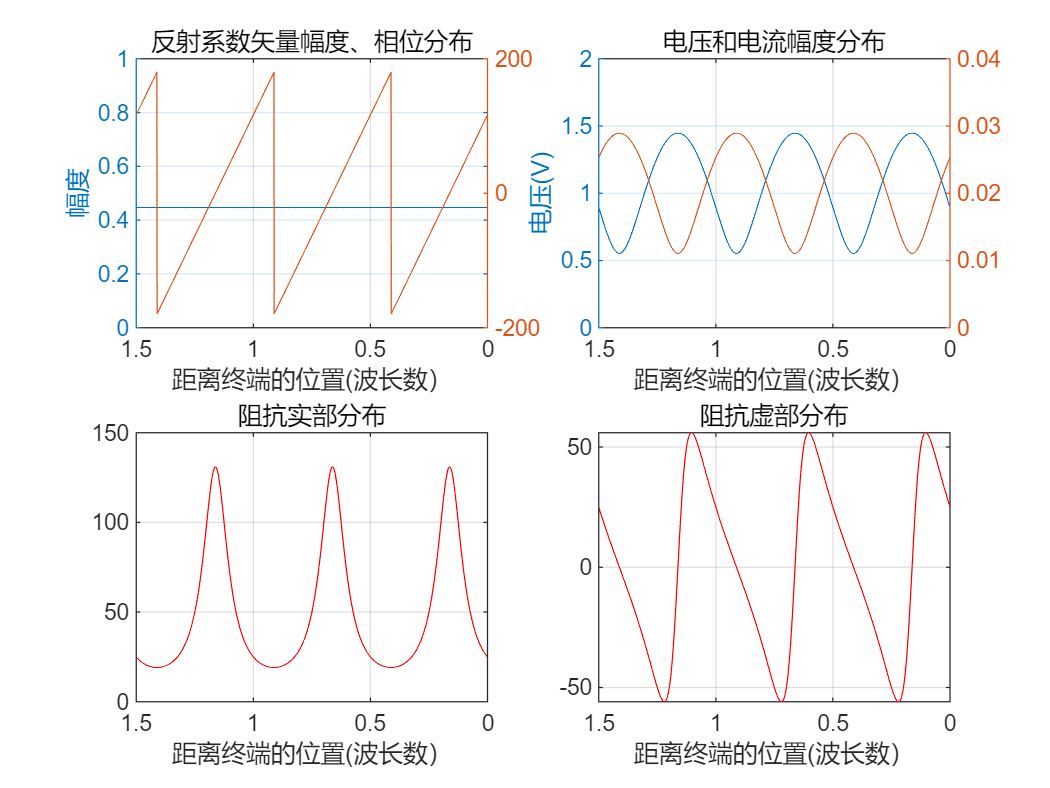

%%%%%%%%%实验条件%%%%%%%%%
Vg=2;
Z0=50;
Rg=50;
Zl=25+25*1i;

%%%%%%%%%参数设置%%%%%%%%%
ztp=0:0.001:1.5;% 位置步长
err=10^(-8);% 精度

%%%%%%%%%公式%%%%%%%%%
% 1.	终端反射系数
gamma0=(Zl-Z0)/(Zl+Z0);
% 2.	传输线上反射系数分布
gamma=gamma0*exp(-1i*4*pi*ztp);
% 3.	传输线上输入阻抗分布
Zin=Z0*(Zl*cos(2*pi*ztp)+1i*Z0*sin(2*pi*ztp))./(Z0*cos(2*pi*ztp)+1i*Zl*sin(2*pi*ztp));
% 4.	源端（即输入端）输入反射系数和输入阻抗
gammaL=gamma0*exp(-1i*2*2*pi*1.5);
ZinL=Z0*(Zl*cos(2*pi*1.5)+1i*Z0*sin(2*pi*1.5))/(Z0*cos(2*pi*1.5)+1i*Zl*sin(2*pi*1.5));
% 5.	源端（即输入端）电压、电流和入射波电压
VL=Vg*ZinL/(Rg+ZinL);
CL=VL/ZinL;
Vinc=(VL+CL*Z0)/2;
% 6.	负载端（即坐标原点处）入射波电压
A1=Vinc*exp(-1i*2*pi*1.5);
% 7.	传输线上电压和电流分布
v_ca0=A1*exp(1i*2*pi*ztp);%幅值
v_ca=v_ca0.*(1+gamma);
i_ca=v_ca0.*(1-gamma)/Z0;



%%%%%%%%%绘制图像%%%%%%%%%
figure(1);
%反射系数幅度和相位分布曲线
subplot(2,2,1);
ax = plotyy(ztp,abs(gamma),ztp,angle(gamma)*180/pi);
set(ax(1),'ylim',[0,1],'ytick',[0:0.2:1]);
set(get(ax(1),'Ylabel'),'string','幅度');
title('反射系数矢量幅度、相位分布');
set(ax,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
%电压电流大小分布曲线
subplot(2,2,2);
ax = plotyy(ztp,abs(v_ca),ztp,abs(i_ca));
set(ax(1),'ylim',[0,Vg],'ytick',[0:Vg/4:Vg]);
set(get(ax(1),'Ylabel'),'string','电压(V)');
set(ax(2),'ylim',[0,Vg/Z0],'ytick',[0:Vg/4/Z0:Vg/Z0]);
title('电压和电流幅度分布');
set(ax,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
%阻抗实部分布曲线
subplot(2,2,3);
realZin = max(-1000,min(1000,real(Zin))); %限制大小在+/-1000以内
plot(ztp,realZin,'r');
title('阻抗实部分布');
set(gca,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;
%阻抗虚部分布曲线
subplot(2,2,4);
imagZin = max(-1000,min(1000,imag(Zin))); %限制大小在+/-1000以内
if(max(abs(imagZin)))<err
    imagZin = imagZin*0;
end
plot(ztp,imagZin,'r');
title('阻抗虚部分布');
set(gca,'Xdir','reverse');  %反转横轴
xlabel('距离终端的位置(波长数）');
grid on;